## Sound analysis lecture

clear
[signal,Fs] = audioread('AudioTest\120BPM_PIANO_C5_simple.wav');


signal = signal(:,1) % signal = toutes les lignes de la première colonne

signal =     0.0005
    0.0010
    0.0007
   -0.0006
   -0.0026
   -0.0042
   -0.0046
   -0.0038
   -0.0022
   -0.0003


FFTSize = 4096;
hopsize = 2000; %changer de nom overlapp, overlap = nombre de samples commun
overlapp = FFTSize -hopsize;

[FFTVector,frequencyBand,newTime] = spectrogram (signal,FFTSize,overlapp,FFTSize-1,Fs,'yaxis')

FFTVector =    0.0297 + 0.0000i  -0.2466 + 0.0000i  -0.0914 + 0.0000i  -0.2311 + 0.0000i   0.1226 + 0.0000i  -0.1117 + 0.0000i   0.2442 + 0.0000i  -0.2227 + 0.0000i   0.0239 + 0.0000i  -0.2527 + 0.0000i   0.1314 + 0.0000i  -0.1748 + 0.0000i   0.2412 + 0.0000i  -0.2264 + 0.0000i   0.0368 + 0.0000i  -0.2474 + 0.0000i   0.1368 + 0.0000i  -0.1845 + 0.0000i   0.2486 + 0.0000i  -0.2356 + 0.0000i   0.0360 + 0.0000i  -0.2474 + 0.0000i   0.1367 + 0.0000i  -0.1833 + 0.0000i   0.2490 + 0.0000i  -0.2359 + 0.0000i   0.0350 + 0.0000i  -0.2466 + 0.0000i   0.1365 + 0.0000i  -0.1836 + 0.0000i   0.2512 + 0.0000i  -0.2357 + 0.0000i   0.0357 + 0.0000i  -0.2468 + 0.0000i   0.1365 + 0.0000i  -0.1840 + 0.0000i   0.2508 + 0.0000i  -0.2351 + 0.0000i   0.0353 + 0.0000i  -0.2473 + 0.0000i   0.1364 + 0.0000i  -0.1845 + 0.0000i   0.2504 + 0.0000i  -0.2354 + 0.0000i   0.0351 + 0.0000i  -0.2473 + 0.0000i   0.1365 + 0.0000i  -0.1842 + 0.0000i   0.2505 + 0.0000i  -0.2354 + 0.0000i
  -0.1633 - 0.1026i  -0.2825 - 0.0792

frequencyBand = 	1.0e+04 *

         0
    0.0012
    0.0023
    0.0035
    0.0047
    0.0059
    0.0070
    0.0082
    0.0094
    0.0105


newTime =     0.0427    0.0843    0.1260    0.1677    0.2093    0.2510    0.2927    0.3343    0.3760    0.4177    0.4593    0.5010    0.5427    0.5843    0.6260    0.6677    0.7093    0.7510    0.7927    0.8343    0.8760    0.9177    0.9593    1.0010    1.0427    1.0843    1.1260    1.1677    1.2093    1.2510    1.2927    1.3343    1.3760    1.4177    1.4593    1.5010    1.5427    1.5843    1.6260    1.6677    1.7093    1.7510    1.7927    1.8343    1.8760    1.9177    1.9593    2.0010    2.0427    2.0843


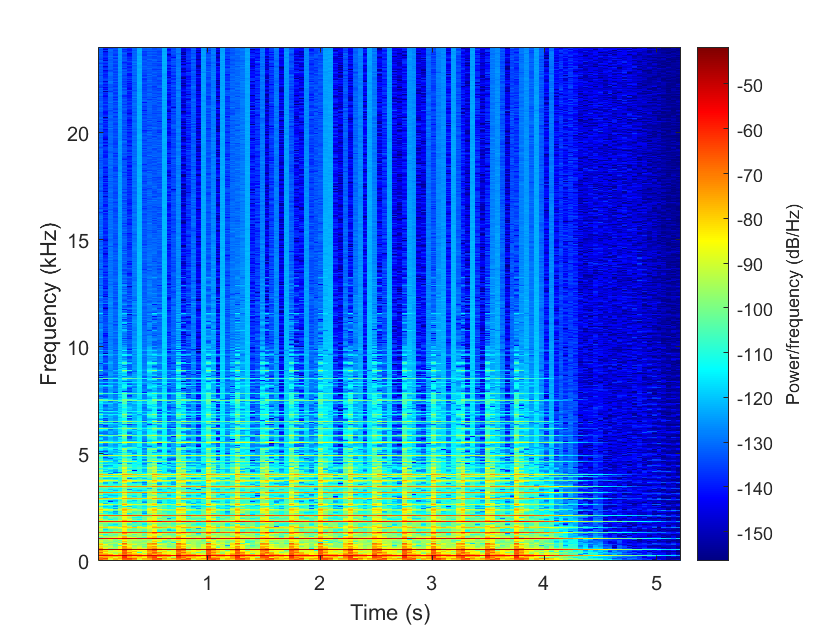

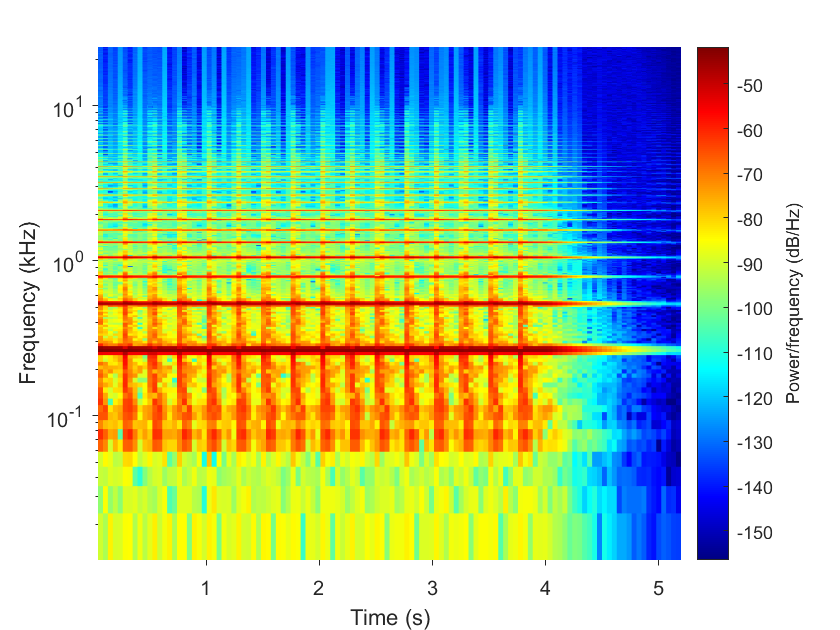

spectrogram (signal,FFTSize,hopsize,FFTSize,Fs,'yaxis');
colormap jet
set(gca, 'YScale', 'log')

N = length(signal)

N = 252250

time = [0:N-1]/Fs

time =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010


%le nombre de FFT a effectuer pour couvrir tout le signal
numberFFT  = size(FFTVector,2)

numberFFT = 125



unwrappedPhase = zeros(FFTSize/2,numberFFT)

unwrappedPhase =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

deltaPhi = zeros(FFTSize/2,numberFFT)

deltaPhi =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

%enveloppe folower
EnveloppeFolow = zeros(numberFFT)

EnveloppeFolow =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

%local energieFolower
LocalEnergieFolow = zeros(numberFFT,1)

LocalEnergieFolow =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


%vector pour garder l'énergie de la FFT - version sans pondération
%fréquentielle
FFT_SimpleEnergie = zeros(numberFFT,1)

FFT_SimpleEnergie =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


%vector pour garder l'énergie de la FFT - version sans pondération
%fréquentielle
FFT_HFC = zeros(numberFFT,1)

FFT_HFC =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



%vector pour enregistrer les différences de spectres entre deux FFT
FFT_spectralDiff = zeros(numberFFT,1)

FFT_spectralDiff =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



sumDeltaPhi = zeros(numberFFT,1)

sumDeltaPhi =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


%new time est la nouvelle Fs, on sample moins vite, on divise Fs par
%l'overlapp




%indexFFT parcours le nombre de FFT a effectuer de 0 à numberFFT-1
%indexPosition parcours la FFT de 1 à la taille de la FFT

for indexFFT = 0:1:numberFFT-1 

    %the value contient la portion de signal a traiter
    %TODO : fonction fenetrage
    theValue = signal(1+indexFFT*hopsize:FFTSize+indexFFT*hopsize);
    
    
    unwrappedPhase(:,indexFFT+1) = angle(FFTVector(:,indexFFT+1));
    
    EnveloppeFolow(indexFFT+1) = 1/FFTSize * sum(abs(theValue));
    LocalEnergieFolow(indexFFT+1) = 1/FFTSize *sum(theValue.^2);
    %la boucle parcours tous les élèments de la FFT
    for indexPosition = 1:1:FFTSize/2         
        %pour chaque FFT, on calcule son énergie et on la met dans un tableau
        FFT_SimpleEnergie(indexFFT+1) = FFT_SimpleEnergie(indexFFT+1,1) + (abs(FFTVector(indexPosition,indexFFT+1)))^2;
        
        FFT_HFC(indexFFT+1,1) = FFT_HFC(indexFFT+1,1) + indexPosition*(abs(FFTVector(indexPosition,indexFFT+1)))^2;
        
        % si on a deja effectuer une FFT
        if(indexFFT > 0)
            %algorithme spectral difference
            
            %difference entre deux bins consecutives
            localSpectralDiff = abs(FFTVector(indexPosition,indexFFT+1)) - abs(FFTVector(indexPosition,indexFFT));
            %on ne garde que les incréments d'énérgie 
            localSpectralDiff = (localSpectralDiff + abs(localSpectralDiff))/2;
            FFT_spectralDiff(indexFFT+1,1) = FFT_spectralDiff(indexFFT+1,1) + localSpectralDiff;
        end
        if(indexFFT>1)
            deltaPhi(indexPosition,indexFFT+1) = unwrappedPhase(indexPosition,indexFFT+1)-2*unwrappedPhase(indexPosition,indexFFT)+unwrappedPhase(indexPosition,indexFFT-1);
        end
    end
    FFT_SimpleEnergie(indexFFT+1,1) = 1/FFTSize *FFT_SimpleEnergie(indexFFT+1,1);
    FFT_HFC(indexFFT+1,1) = 1/FFTSize *FFT_HFC(indexFFT+1,1);
    
    sumDeltaPhi(indexFFT+1,1) = 1/FFTSize* sum(abs(deltaPhi(:,indexFFT+1)));
    
end

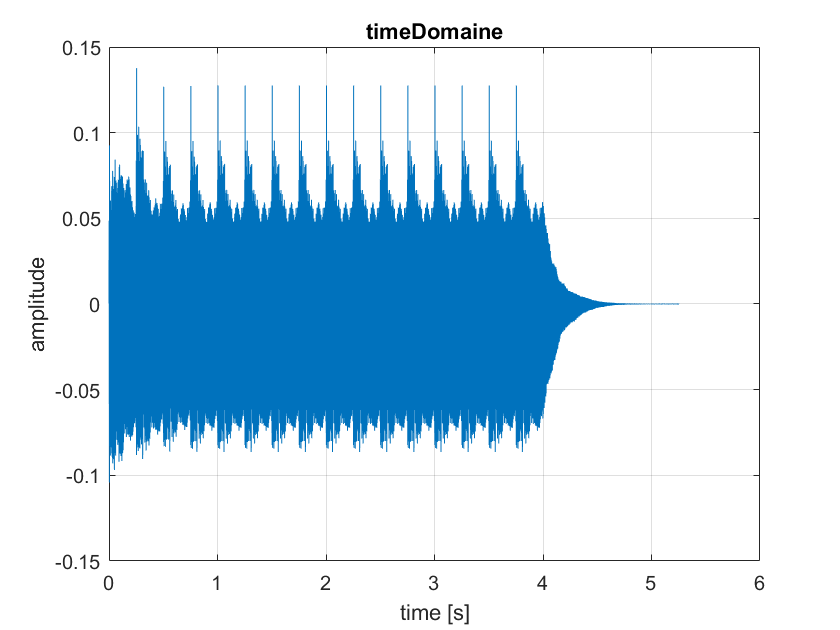

%time domaine signal
plot(time,signal)
grid on
xlabel("time [s]")
ylabel("amplitude")
title("timeDomaine")

%stat info
maxValue = max(signal)

maxValue = 0.1376

minValue = min(signal)

minValue = -0.1042

meanValue = mean(signal)

meanValue = 5.4357e-07

stdValue = std(signal) %standart deviation

stdValue = 0.0339

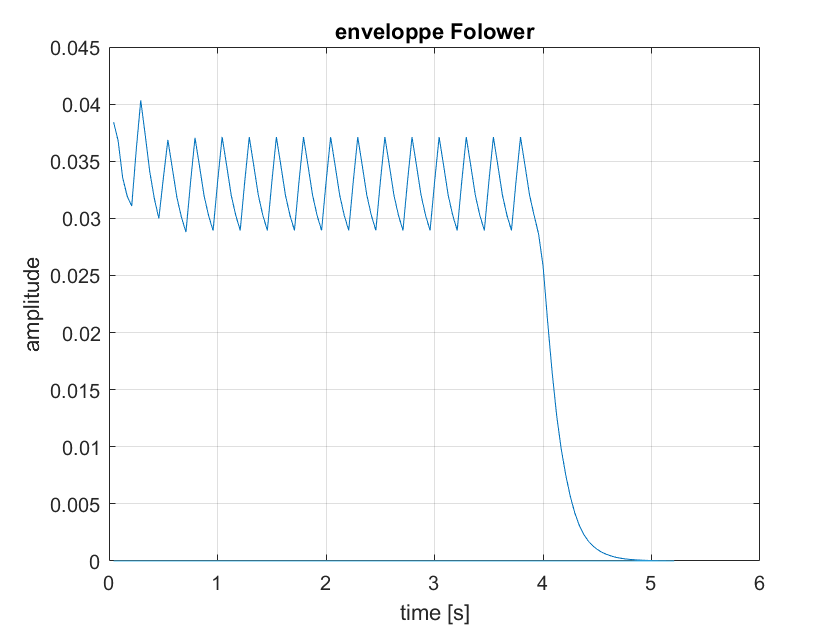

plot(newTime ,EnveloppeFolow)
grid on
xlabel("time [s]")
ylabel("amplitude")
title("enveloppe Folower")

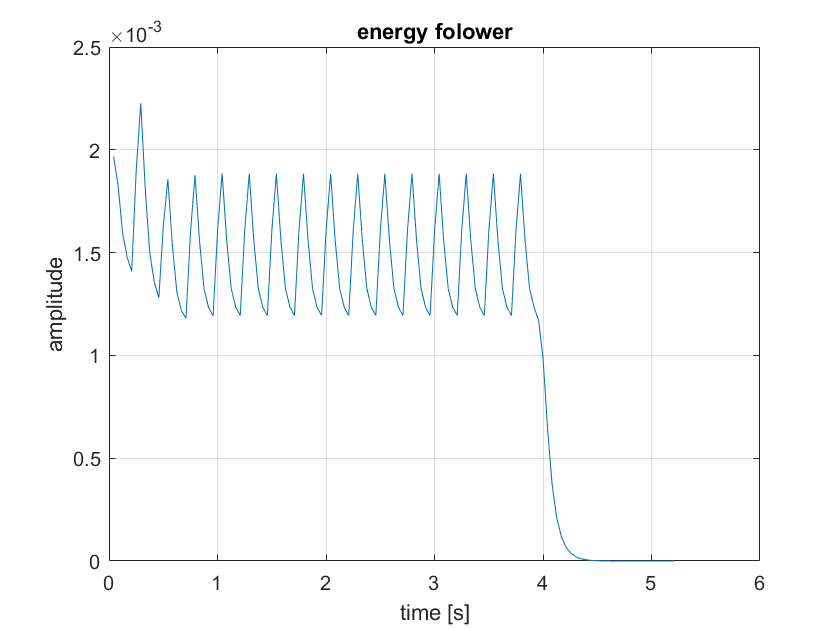



plot(newTime,LocalEnergieFolow)
grid on
xlabel("time [s]")
ylabel("amplitude")
title("energy folower")

LocalEnergieFolow_maxValue = max(LocalEnergieFolow)

LocalEnergieFolow_maxValue = 0.0022

LocalEnergieFolow_minValue = min(LocalEnergieFolow)

LocalEnergieFolow_minValue = 1.9054e-10

LocalEnergieFolow_meanValue = mean(LocalEnergieFolow)

LocalEnergieFolow_meanValue = 0.0012

LocalEnergieFolow_stdValue = std(LocalEnergieFolow) %standart deviation

LocalEnergieFolow_stdValue = 6.5188e-04

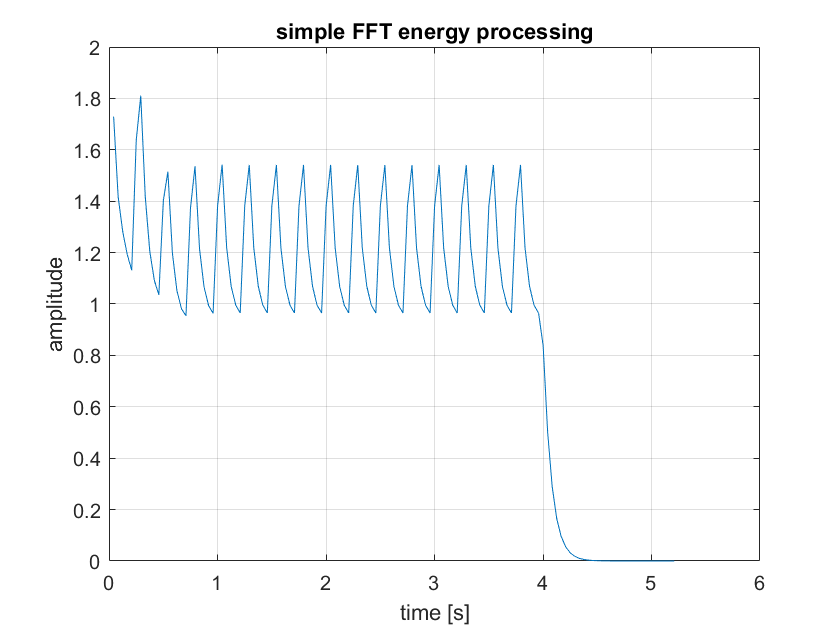

plot(newTime,FFT_SimpleEnergie)
grid on
xlabel("time [s]")
ylabel("amplitude")
title("simple FFT energy processing")

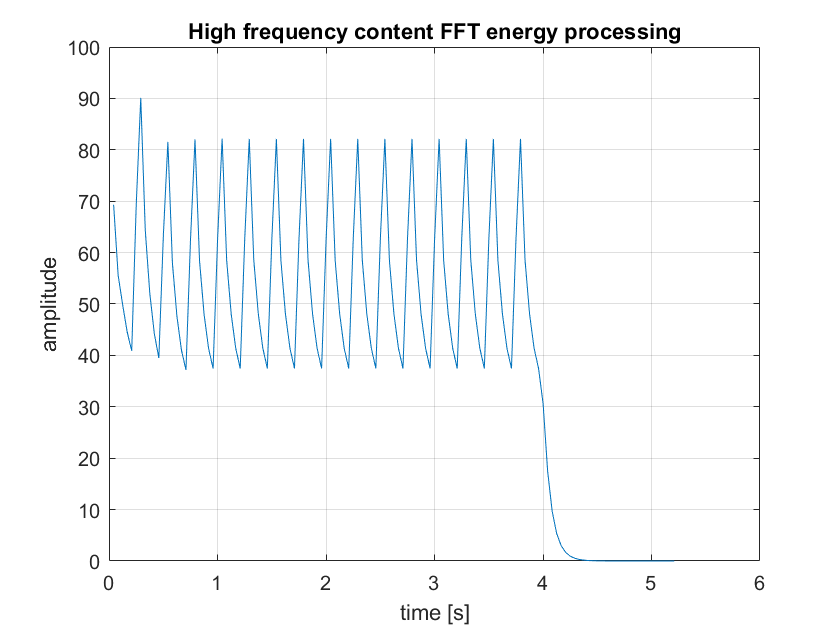

plot(newTime,FFT_HFC)
grid on
xlabel("time [s]")
ylabel("amplitude")
title("High frequency content FFT energy processing")

%stat info
FFT_HFC_maxValue = max(FFT_HFC)

FFT_HFC_maxValue = 90.1042

FFT_HFC_minValue = min(FFT_HFC)

FFT_HFC_minValue = 1.7969e-05

FFT_HFC_meanValue = mean(FFT_HFC)

FFT_HFC_meanValue = 42.4929

FFT_HFC_stdValue = std(FFT_HFC) %standart deviation

FFT_HFC_stdValue = 26.3625

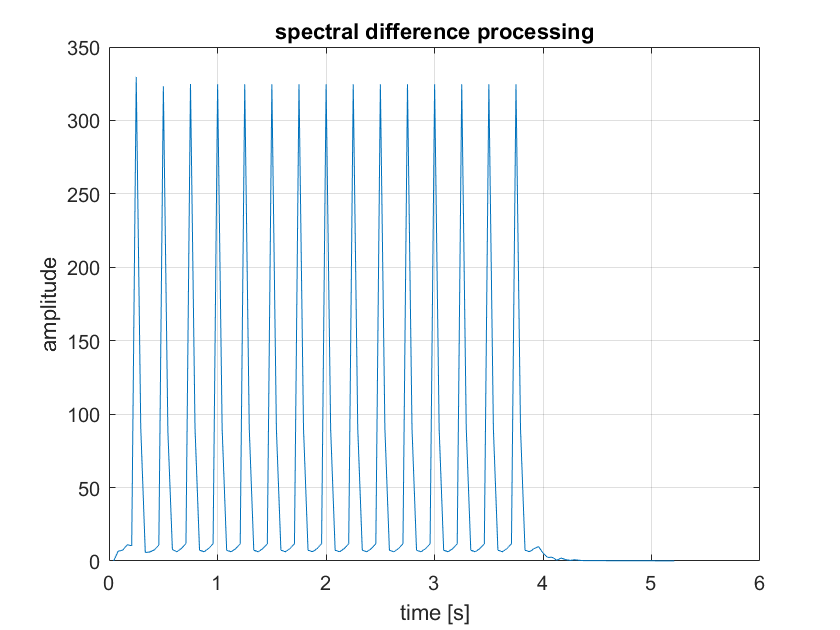

plot(newTime,FFT_spectralDiff)
grid on
xlabel("time [s]")
ylabel("amplitude")
title("spectral difference processing")

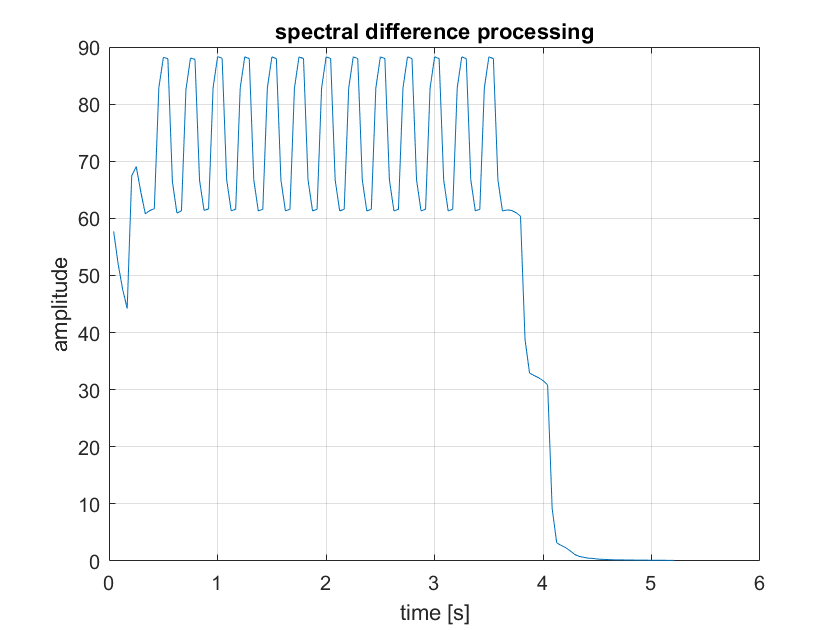


M = movmean(FFT_spectralDiff,15);
plot(newTime,M)
grid on
xlabel("time [s]")
ylabel("amplitude")
title("spectral difference processing")

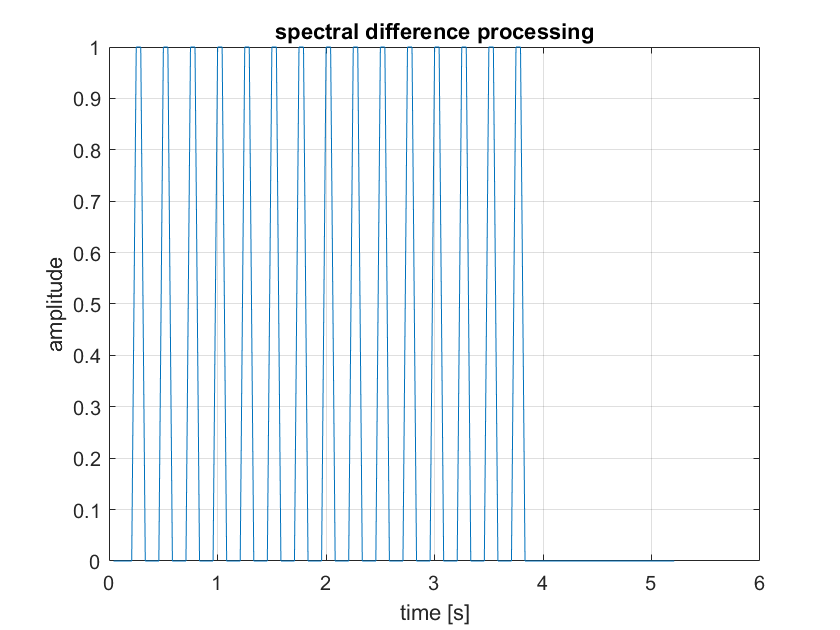

onset = zeros(size(M));
onsetTime = zeros(size(M));

for indexTime = 1 : size(M)
    if(FFT_spectralDiff(indexTime) >= M(indexTime))
        if(LocalEnergieFolow(indexTime)> LocalEnergieFolow_stdValue)
            onset(indexTime) = 1;
        end
    else
        onset(indexTime) = 0;
    end
    if(onset(indexTime) == 1 && onset(indexTime-1) == 0)
        onsetTime(indexTime) =1;
    
    end
    
end
plot(newTime,onset)
grid on
xlabel("time [s]")
ylabel("amplitude")
title("spectral difference processing")

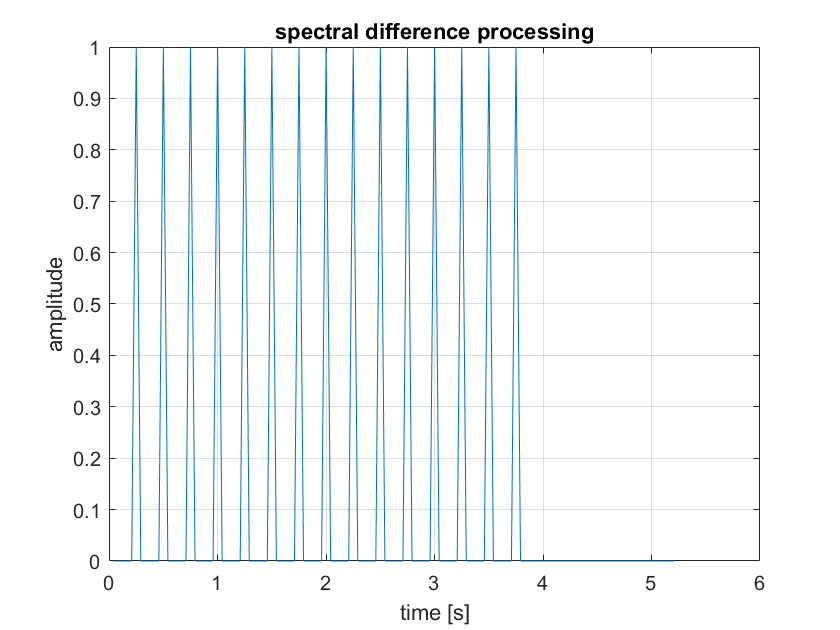

plot(newTime,onsetTime)
grid on
xlabel("time [s]")
ylabel("amplitude")
title("spectral difference processing")

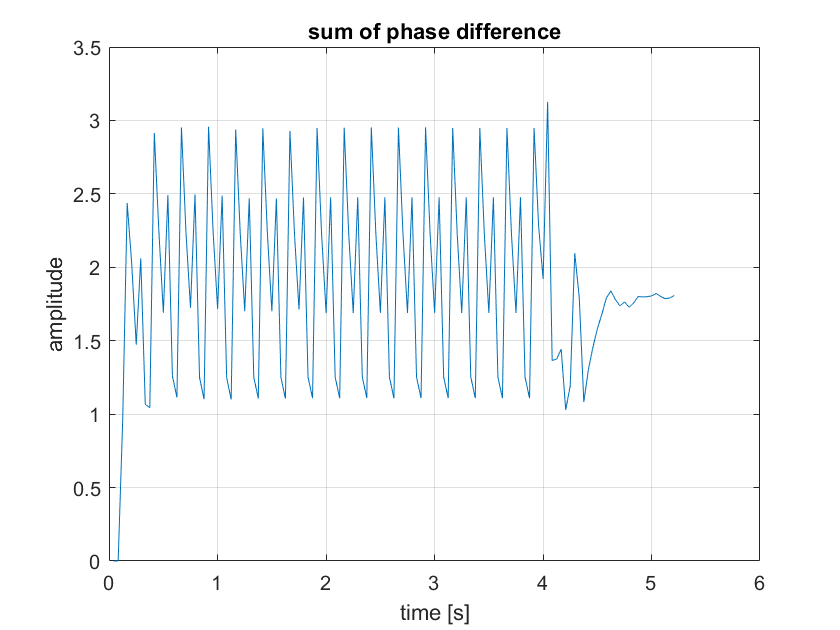

plot(newTime,sumDeltaPhi)
grid on
xlabel("time [s]")
ylabel("amplitude")
title("sum of phase difference")